# An introduction to Scale Invariant Feature Transform (SIFT)

**This MATLAB Livescript tries to explain how the SIFT feature detector, descriptor and matcher works.**

#### Toolbox requirements: This livescript uses the Harris detector from the CV Toolbox and the Image processing Toolbox

#### Sources: Sources are found at the end of this live-script. I refer to sources in text and code with (X) where X is the source reference number

## IMPORTANT

Some cells create 3D plots that for some reason use a lot of system memory that can't be freed by any matlab command. In addition, Matlabs RAM management under UNIX is especially bad.** If you are using UNIX and your system has less than 24GB of RAM, please disable 3D plotting to avoid that your system just terminates Matlab because of excessive RAM usage. If you are using Windows and your system has less than 16GB of RAM, please also disable 3D plotting**.

% check the box if your system has less than 24GB (UNIX) or 16GB (Windows)
% of RAM.
disable_3D_plotting = false;

If you do not disable 3D plotting and run out of RAM, your System might just terminate Matlab and you can't run this livescript in a single run. You can of course restart Matlab after your first go through the livescript, enable 3D plotting and only run the cells that used 3D plotting.

This live-script will guide you through the SIFT feature extractor which is composed of a detector, descriptor and matcher. I will first show you step by step the detector implementation and explain why SIFT does the things it does. Once the detector is finished, I briefly go over the descriptor and matcher part of SIFT.

SIFT is programmed in 4 Steps:

- Step 1 & 2: SIFT detector

- Step 3: SIFT descriptor

- Step 4: SIFT matcher

Only the first two steps are technically part of the assignment which is why Step 3 and 4 are explained only very briefly. However, their implementation is needed for the comarison after the SIFT implementation. This Matlab implementation is based on (3) which goes in detail through the SIFT feature extractor. To reduce the length of this script, plotting functions were moved to external files (`func_plot_*`) which are not important to understand SIFT.

## What are feature detectors and why should you care?

Feature detectors are not only useful to create arguably lengthy programming homeworks but you can also use them to solve real-world tasks like image-stitching, pose-estimation or scene-reconstruction. A feature is a set of derived values that are as informative and unique compared to the local or global sampled space as possible. In image processing, a feature can for example be a corner, since there is a distinctive gradient at corner points which make them unique compared to the local neighborhood. By no means are features limited to corners, they can also be so-called BLOBs, which can be more general structures of an image that are unique. Feature detectors aim to find the most distinctive features in as little time as possible. These features ideally are invariant to various image transformations like translation, rotation, scaling, shearing or illumination changes. Invariance w.r.t. these changes make a feature stable and a stable feature of an object is more likely to be found again in a different image taken from a different perspective.

## Comparison measures 

The problem statement for feature detectors to find stable and unique features of images make them hard to compare: which image do you choose to make it fair? Some detectors might be better at recognizing features of circular structures, some are better at recognizing features of rectangular structures. In papers like (4), a single image is used and transformed for comparison, however, this approach might be far off from actual real-world usecases like the ones mentioned. It is hard to come up with measures that indicate: 

*this feature detector will **always** outperform that feature detector*

It will depend on the use-case of the feature detector which measures matter and which do not. I have chosen a few that I think are important considerations for a lot of use-cases, namely:

- Speed: how fast is the algorithm?

- Complexity: how hard is it to implement and understand?

- Feature quality: what features does the algorithm detect (edges, corners, BLOBs, ridges, etc..) and how useful are they?

- Feature matching: how robust is matching performance w.r.t. certain image transformations?

Some measures are already given in (4), however, I find that they are especially lacking the feature matching performance when perspective is changed, which I will investigate later on.

## Loading and preparing a standard test image

You might recognize the example image I'm using here from the lecture. This image is often used as a test image for all kinds of image processing tools (you might even find it in papers). Lenna (her real name is Lena Sjööblom) was a swedish model and this picture of her is actually a cropped version of a playboy issue from 1972. The IEEE Professional Communication Society released a 28 pages [newsletter](http://www.lenna.org/pcs_mirror/may_june01.pdf) explaining the whole story if you are interested.

% load the image
I = imread("lenna.tif");

% transform it to grayscale
I = rgb2gray(I);

% check out the image
figure;
colormap("gray");
imshow(I);

% cast it to double so we can work with it
I_original = double(I);
% normalize the image
I = im2double(I);

## SIFT Step 1: Detection of Scale-Space extrema

The first step for SIFT is already substantially different from the Harris corner detector (HCD). In fact, only one step of SIFT is similar to HCD to which we will come later. An attribute that distinguishes SIFT from Harris in terms of detection performance is **scale invariability** (hence the Scale Invariant part in SIFTs name). That means that corresponding features of two images can still be found with a high accuracy, even if one image is significantly scaled up or down (*zooming in* or *zooming out*). For this to work, you somehow need to determine features that are invariant to scaling, or in other words, features that can easily be recognized no matter the scaling of the image.

While the Harris feature extractor starts with computing the image gradient and harris meassures of each pixel, SIFT starts by transforming the image in a so called **scale-space**. This sounds more exotic than it really is: All you need to do is blur the image. You can do this by convolving the image with a 2D gaussian filter. 

### Scale-space transform

The idea is the following: If you blur the image, you **lose very fine details** (or in academic language: "suppressing high-frequency spacial information"). But you will still be able to make out rough structures in a blurred image right? That means that you can still recognize **structural features** of blurred objects. Those "more general" features can also more easily be recognized if the image was scaled down (zooming out) because zooming out is nothing else than decreasing the resolution of an object in the image, hence, losing very fine details of that object. 

The reverse of course also works: if the second image is scaled up (zooming in), then the blurring of it will reduce it to features that are more easily recognized in the first image that was not scaled up. This *easier matching* in scaled versions will thus drive the scale invariability of the SIFT feature extractor. The scale invariability of a feature is also called **feature stability**, since it indicates it's resistance to scaling.

The scale-space variable $\sigma$ is the variance of the gaussian filter used to blur the image. This means that at the origin in scale-space $\sigma =0$ which is the unblurred, original image. The higher $\sigma$ gets, the blurrier the image gets. Going along the $\sigma$ axis in scale-space, you would notice that your image gets blurrier to a point where the image gets so washed out that you can't make out any detail anymore. Intuitively, you can think of $\sigma$ as the amount of beer you have drunk. The more you drink, the blurrier it gets. Let me recall the 2D gaussian filter for you:

### 
$$G(x, y, \sigma) = \frac{1}{2 \pi \sigma^2}e^{-(x^2+y^2)/2\sigma^2}$$


Using our gaussian kernel, we can compute the scale-space representation $L$ of our original image $I$ with a simple convolution in $x$ and $y$ direction (2D convolution):

### 
$$L(x, y, \sigma) = G(x, y, \sigma) * I(x, y)$$


I will refer to $L$ later on as a **scale**. For example, a high scale would be a $L\left(x,y,\sigma \right)$ with a large $\sigma$.

You can find the implementation of the scale-space transformation in `func_sspace_trafo.mlx.` It simply performs a 2D convolution with a normalized gaussian filter and adapts the gaussian filter size to the variance (same as HW1). However, adapting the filter size means that as we increase $\sigma$, our filter size will grow to unholy sizes. This can have a big impact on performance. That is why you can give `func_sspace_trafo` the `sigma` that you currently want to convolve with as the second argument and a `base_sigma` as third argument as the initial sigma where you start in scale-space. If you want to adapt the gaussian filter size to your current `sigma` you can set `adapt_filter_size=true` to adapt the size to `sigma` instead of `base_sigma`.

Let's see how our test image looks like at different values for $\sigma$. Feel free to play around with the slider to get a feeling on how the image changes in scale-space:

% our scale-space variable. Use the slider to change the value
sigma = 13;

% our initial sigma. It will become clear later what that means.
base_sigma = 0.8;

% If you set adapt_filter_size to true, it will use sigma to calculate the filter size. 
% If you set it to false it will use base_sigma. Notice that if you adapt the filter size
% and increase sigma the image gets much blurrier because the filter size grows with sigma.
adapt_filter_size = true;

% compute the scale at the given sigma. Note that func_sspace_trafo has 4 inputs (one is
% optional). I is our grayscale image. sigma is the variance for the
% gaussian filter. base_sigma is only used if adapt_filter_size=true and
% will determine the gaussian filter size in this case
% (filter_size=5*base_sigma).
L = func_sspace_trafo(I, sigma, base_sigma, adapt_filter_size=adapt_filter_size);

% show the result
figure('position', [0, 0, 1000, 600]);
colormap("gray");
subplot(1, 2, 1);
imshow(I, [min(I, [], 'all'), max(I, [], 'all')]);
title('Original');
subplot(1, 2, 2);
imshow(L, [min(L, [], 'all'), max(L, [], 'all')]);
title("Scale-space (sigma=" + sigma + ")");

You should notice that as $\sigma$ increases, you are able to make out lesser details, but basic structural features persist. This is the main idea.

### Feature stability: Harris vs SIFT, Gradient-based vs Scale-Space-based

For a feature detector, you want to select the most stable features of your image that you return at the end as an output. But how do you find them? You compute some sort of metric that tells you how stable a certain pixel might be and find the extreme candidates (minima and maxima). 

The **Harris** detector** calculates the Harris criterion **$h$** that is based on the image gradient** for each pixel and then finds all pixels with a Harris criterion value over a certain threshold, indicating that a pixel is a corner. Recall the formula for the Harris criterion:

### 
$$h = det(G(x, y)) - k(tr(G(x, y)))^2$$


The **SIFT** detector uses the scale-space to determine the most interesting features. For this, it **calculates the difference-of-Gaussian (DoG) function **$D$** based on the scale-space representation**:

### 
$$D(x, y, \sigma) = L(x, y, k\sigma) - L(x, y, \sigma)$$


Notice that this DoG is calculated using** scale-space representations of the same image but with different values of **$\sigma$ (substracting $L\left(\sigma \right)$ from $L\left(k\sigma \right)$ where k is a positive scalar, thus subtracting a lower scale from a higher scale). You then select the features that have local extrema $D$ values.

**One advantage over the Harris detector is, that the maxima and minima (aka extrema) of the **$D$** function are better indicators of stable features than maxima of the **$h$** function that the Harris detector uses (1).**

### Building the scale-space

The SIFT algorithm groups different intervals of $\sigma$ in scale-space into **octaves**. This is visualized in the following picture taken from (1):

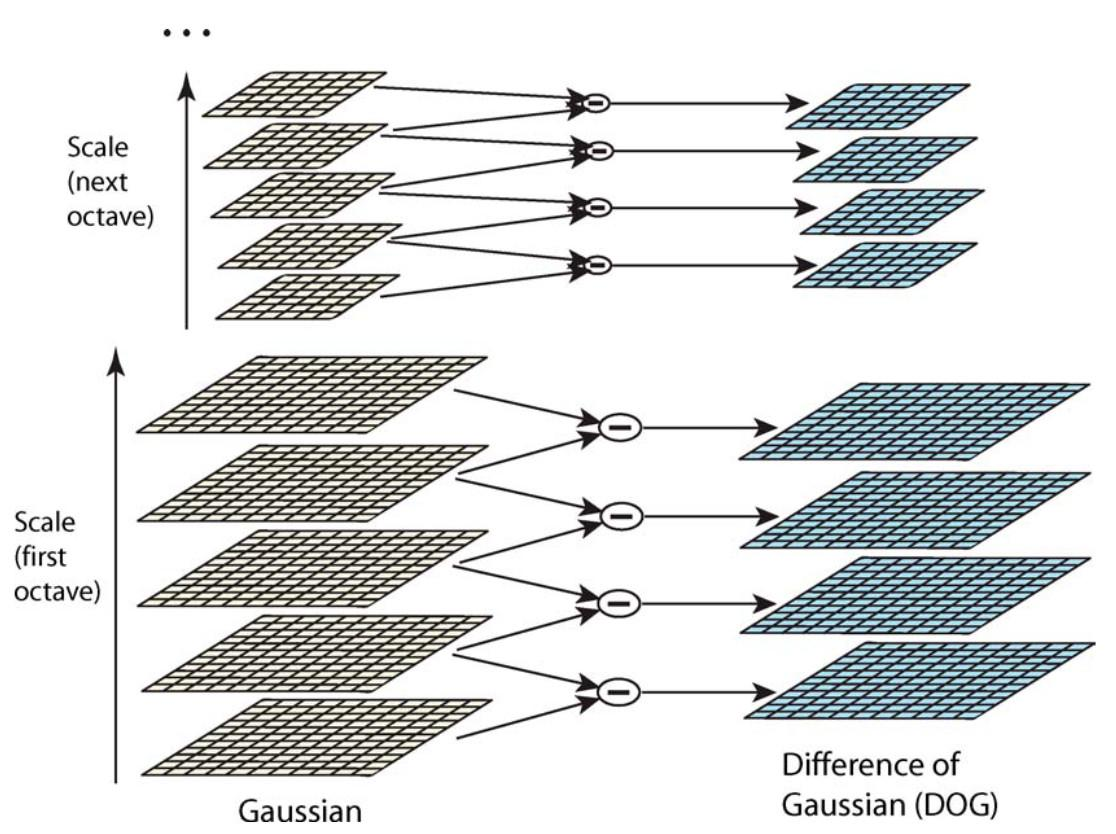

The left stack represents our scale-space of transformed images $L$, also called scales. It starts with a scale $L\left(\sigma_{\textrm{base}} \right)$ at $\sigma =\sigma_{\textrm{base}}$ as the first entry of the first octave (here the most bottom left grid). To get $L\left(\sigma_{\textrm{base}} \right)$ from our input image $I$ we upscale $I$ by a factor of $2$ by bilinear interpolation. So, a 512x512 image would be upscaled to 1024x1024. We then transform the upscaled image to scale-space by applying a 2D gaussian filter with the following variance (3): 

### 
$$\sigma(1) = 2\sqrt{\sigma_{base}^2 - 0.5^2}$$


**Each octave consists of **$s+3$** iteratively transformed scales**. This $s$ is a tunable parameter of the algorithm and will increase computational complexity (as you need to compute more scales) but it also increases granularity of sampling in scale-space. You slowly increase $\sigma$ by refiltering the first scale over and over again with a gaussian filter. **To get the **$j$**-th scale you perform the scale-space transformation on the **$j-1$**-th scale with **$\sigma \left(j\right)$** according to (3)**:

### 
$$\sigma(j) = \frac{\sigma_{base}}{0.5}\sqrt{2^{\frac{2j}{s}} - 2^{\frac{2(j-1)}{s}}}$$


### 
$$L_j = G(\sigma(j))*L_{j-1}$$


That looks complicated. Why choose $\sigma \left(j\right)$ like that? Well, if you apply the scale-space transformation iteratively (smoothing an already smoothed scale), the variances combine and increase. By choosing $\sigma \left(j\right)$ like that, we will have $\sigma \left(s+1\right)=2\sigma_{\textrm{base}}$ (double the initial value) after $s+1$ steps. This doubling is how an octave is defined and there is a trick to save computational power that I will explain in the next cell.

Let's compute the first octave and its corresponding difference of gaussian (DoG):

% base sigma (initial sigma. this is where the algorithm starts in scale-space)
base_sigma = 0.8;

% number of scales (number of scale-space transformed images per octave)
% Note: the octave will consist of s+3 scales, I will explain later why
s = 3;
n_scales = s+3;

% create a cell that will hold our computed scales and DoGs
octave = {1, n_scales};

% Note: we have one less DoGs than scales per octave
dogs = {1, n_scales-1};

% this is our sigma(1) calculated according to (3)
first_sigma = 2*sqrt(base_sigma^2 - 0.5^2);

% upscale the original image by a factor of 2
upscaled_img = imresize(I, 2, "bilinear");

% compute the first scale of the first octave. this is simply the
% scale-space transformed of the upscaled input image. We already upscaled
% the image and calculated sigma(1) so we can apply the scale-space
% transformation
octave{1, 1} = func_sspace_trafo(upscaled_img, first_sigma, base_sigma, adapt_filter_size=true);

% compute the rest of the octave. Note: we start the for loop at index 2
% because we already calculated the first scale
for j = 2:n_scales
    % compute the sigma for the current scale according to (3)
    sigma = (base_sigma/0.5)*sqrt(2^((2*j)/s) - 2^((2*(j-1))/s));
    
    % perform the scale-space transformation on the previous scale (j-1) in the
    % octave to get the current scale
    octave{1, j} = func_sspace_trafo(octave{1, j-1}, sigma, base_sigma, adapt_filter_size=true);
    
    % now that we have the j-th and j-1-th scale, we can compute the
    % DoG by just subtracting the two. The index for the DoG will be the
    % index of the lower scale in the subtraction (j-1).
    dogs{1, j-1} = func_diff_of_gauss(octave{1, j}, octave{1, j-1});
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PLOT ONLY IF 3D PLOTTING IS ENABLED!
if ~disable_3D_plotting
    %plot the octave and DoG (you dont need to understand how this works, it is not part of SIFT)
    tmp_fig = func_plot_first_octave(base_sigma, n_scales, s, octave, dogs);
end

If 3D plotting is not disabled, you should see that as you increase the scale, the image gets blurrier. From the scale axis you can see that the scale at position $s+1$ has exactly double the initial sigma $\sigma_{\textrm{base}}$ . You also might notice that the **corresponding DoGs start highlighting more structural features as we go higher in scale-space**.

What happens in the next octave? There is a trick to save computational power. After you surpass a $\sigma =2\sigma_{\textrm{base}}$ in the first octave, you effectively have lost the details that you would lose by scaling the image down by a factor of two. That means: You dont lose information if you shrink the image for the next octave by a factor of two BUT what you gain is computational efficiency since the convolution operation is significantly shorted. The SIFT algorithm uses exactly this, by starting a succeeding octave with a down-sampled version of the preceeding octave. The image that is used for downsampling is the image that is 2 images from the top of the stack at position $s+1$ which is exactly the image where $\sigma$ has doubled w.r.t. to the first image in the octave.

Let's compute the whole scale space (the computation has been moved to `func_compute_scale_space.mlx`, feel free to look at the comments there but it is largely the code already explained above, it just loops for the desired amount of octaves specified).

% close previous figure to save RAM
if ~disable_3D_plotting
    close(tmp_fig);
end


% define a base_sigma. This is the default value given in (3)
base_sigma = 0.8;

% define the amount of octaves
n_octaves = 4;

% define s (an octave will have s+3 samples)
s = 5;

% Compute all octaves and dogs. Have a look at the function file to understand how it exactly works.
[octaves, dogs] = func_compute_scale_space(I, base_sigma, s, n_octaves, adapt_filter_size=true);


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PLOT ONLY IF 3D PLOTTING IS ENABLED!
if ~disable_3D_plotting
    % plot all octaves (not part of SIFT)
    tmp_fig = func_plot_octaves(base_sigma, s, octaves);
end

What should be visible here (if 3D plotting is enabled) is that with each octave, the image size is halfed in both dimensions. This happens because we downscale the $s+1$ -th scale of the previous octave to get the first scale for the current octave. This means we don't introduce additional blur between the $s+1$-the scale of the preceeding octave and the first scale of the current octave, so there is hardly any difference noticable in the amount of details when you compare the $s+1$-th image from a previous octave with the first image of the next octave. It should be visible how the overall resolution changes along the octaves.

Now lets also have a look at the difference of gaussian for the corresponding octaves, if 3D plotting is not disabled:

% close previous figure to save RAM
if ~disable_3D_plotting
    close(tmp_fig);
end



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% PLOT ONLY IF 3D PLOTTING IS ENABLED!
if ~disable_3D_plotting
    % plot all DoGs (not part of SIFT)
    tmp_fig = func_plot_dogs(base_sigma, s, dogs);
end

The DoGs start highlighting more general structures as they evolve, exactly what we need for scale invariance! If you imagine stacking these octaves ontop of each other, they build a pyramid, since at the start of each new DoG octave, the image x and y dimensions are halfed. This pyramid is also often called **Laplacian Pyramid** since the **difference-of-gaussians** (DoGs) we used **is a computational efficient approximation of the Laplacian of the image**.

### Finding extrema

Let's now find local extrema in the DoG octaves. Remember, the extrema of the $D$ function have a strong correlation with feature stability, so the pixels that show these properties will be our keypoints. Have a look at the figure from (1):

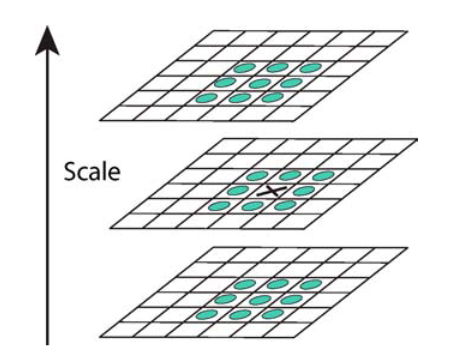

The difficulty is now, that we not only have to compare each pixel to its direct neighbours in the image dimensions but also to its direct neighbours in scale-space dimension. So we cut a 3x3x3 pixel cube out and check if the center pixel has the highest or lowest $D$ value out of all pixels in this cube. If yes, we store it's coordinates $x,y$ along with the corresponding octave $i$ and scale $j$ and also the DoG value $d$. So an extremum $e$ will look like:


$$e={\left\lbrack x,y,i,j,d\right\rbrack }^T$$


Important: $x$ and $y$ are coordinates relative to the current octave scale, NOT to the original image (remember the downscaling! Image sizes are halfed at the beginning of each octave). The following code performs the search:

% close previous figure to save RAM
if ~disable_3D_plotting
    close(tmp_fig);
end



% keep track of the amount of extrema found
extrem_count = 0;

% keep track of the number of iterations done
iter_count = 0;

% create an array that will hold all the extremas we find. I fill it with
% an initial dummy entry and then append the found extremas column wise.
% After all extremas are found, I delete this dummy entry.
extrema = zeros(5, 1);

% get dimensions of the DoG cell
% n_dog_octaves should be equal to the number of octaves we have
% n_dogs is the number of DoG images (scales) we have per DoG octave (should be s+2)
[n_dog_octaves, n_dogs] = size(dogs);


% iterate through each dog octave
for i = 1:n_dog_octaves
    
    % get the DoG image dimensions (x and y) for the current DoG octave.
    % remember that as we go to the next octave, the image dimensions are
    % halfed. So it is important to get the correct image dimensions to
    % search the image for local extrema
    [xdog, ydog] = size(dogs{i, 1});
    
    % iterate through the DoG octave. Note that we start at the second
    % layer (because we need something to compare to downwards) and end at
    % the second to last layer (because we need something to compare to
    % upwards)
    j_iter = n_dogs-1;
    for j = 2:j_iter
        
        % go through the image in x direction. Again: start at 2 and end at
        % the second to last index, because we need neighbors to compare
        % to. This also means we automatically discard extrema that lie on
        % the image border.
        k_iter = xdog-1;
        for k = 2:k_iter
            
            % go through the image in y direction, also from 2 to the
            % second to last one for the same reason as above
            l_iter = ydog-1;
            for l = 2:l_iter
                
                % since this is the most inner for loop, we count the
                % amount of iterations here.
                iter_count = iter_count + 1;
                
                % get the DoG value of the current pixel. We access
                % the j-th scale of the i-th octave in the dog cell. This
                % will give us the DoG image in which we then access the
                % pixel at position (k, l)
                curr_value = dogs{i, j}(k, l);
                
                % get the direct neighbors in the current plane. We
                % basically select the 3x3 area around the pixel we are
                % currently interested in.
                plane_neighbours = dogs{i, j}(k-1:k+1, l-1:l+1);
                
                % set the center (current value) to something lower than
                % the current value to avoid that it later on compares this
                % value to itself resulting in an equal value (non-extrema)
                plane_neighbours(2, 2) = plane_neighbours(2, 2) - 1;
                
                
                % check if the current pixel is the largest in the plane.
                % The matrix comparison gives us a logical array indicating
                % if the respective element is larger than the curr_value.
                % Since we decreased the center entry, this is always true
                % for the center. If the surrounding 8 pixels also have
                % smaller DoG values, the 3x3 logical array will be filled
                % with logical ones. Thus, summing them equals to 9
                if sum(curr_value > plane_neighbours, "all") == 9
                    
                    % check if all lower level neighbors are smaller.
                    % Notice the j-1, which is the j-1 th scale of the
                    % current octave. Because we started at the second
                    % scale, there is always a lower scale.
                    bottom_plane_neighbors = dogs{i, j-1}(k-1:k+1, l-1:l+1);
                    if sum(curr_value > bottom_plane_neighbors, "all") == 9
                        
                        % check if all higher scale neighbors are smaller.
                        % Because we are only iterating j until n_dogs-1
                        % there is always a higher scale.
                        top_plane_neighbors = dogs{i, j+1}(k-1:k+1, l-1:l+1);
                        if sum(curr_value > top_plane_neighbors, "all") == 9
                            
                            % append the 5x1 vector of (x, y, i, j, d) to
                            % our extrema array.
                            extrema = [extrema [k; l; i; j; curr_value]];
                            
                            % increase our counter of extremas since we
                            % just added an extrema
                            extrem_count = extrem_count + 1;
                        end
                    end
                else
                    % okay, the pixel was not a maximum, but maybe it is a
                    % minimum. Keep in mind that we substracted 1 to the center
                    % pixel to avoid comparing it to itself. we now add 2
                    % so the center pixel is definitely higher than the
                    % original center pixel value (current value)
                    plane_neighbours(2, 2) = plane_neighbours(2, 2) + 2;
                    if sum(curr_value < plane_neighbours, "all") == 9
                        
                        % check if all lower plane neighbors are larger
                        bottom_plane_neighbors = dogs{i, j-1}(k-1:k+1, l-1:l+1);
                        if sum(curr_value < bottom_plane_neighbors, "all") == 9
                            
                            % check if all higher plane neighbors are
                            % larger
                            top_plane_neighbors = dogs{i, j+1}(k-1:k+1, l-1:l+1);
                            if sum(curr_value < top_plane_neighbors, "all") == 9
                                
                                % add it to extremas. Works exactly as
                                % above.
                                extrema = [extrema [k; l; i; j; curr_value]];
                                extrem_count = extrem_count + 1;
                            end
                        end
                    end
                end
            end
        end
    end
end

% delete the first dummy entry in extrema
extrema(:, 1) = [];

disp("Found: " + extrem_count + " extrema in " + iter_count + " iterations");

Before you say anything: I know, 4 nested for loops are not efficient. This little maneuver cost us almost 7 million iterations.  But I think the way I built it is the easiest to understand it and follow the code (at least it was for me). 

Looking at the extrema count (should be in the order of 1000s) we will need to sort some of them out, which we will do in the next steps. Before we do that, it might be interesting to compare the intermediate result of SIFT with the already known Harris corner detector. I will use the CV-Toolbox for the Harris implementation:

% we need to compute the positions in the original image for each extremum
% found. Remember that we downscale the image at the start of each octave
% so we need to calculate the position of the absolute position for
% plotting
scaled_extrema = zeros(5, 1);
for i = 1:extrem_count
    curr_extrema = extrema(:, i);
    factor = 0.5*2^(curr_extrema(3) - 1);
    curr_extrema(1:2) = curr_extrema(1:2) * factor;
    
    scaled_extrema = [scaled_extrema curr_extrema];
end

% detect harris features with CV-toolbox
harris_extrema = detectHarrisFeatures(I);

% plot intermediate comparison, not part of SIFT
func_plot_inter_comp1(scaled_extrema, harris_extrema, I_original);

So this is SIFTs *raw* feature output without any extrema filtering. The majority of features will be discarded in the next steps. You can't really make out anything yet.

## SIFT Step 2: Accurate keypoint localization and refinement

So let's *sift* through our extrema to refine our feature set (pun intended). As we climb the **laplacian pyramid**, we downsample the image recursively. This means, a pixel in a high scale of a high octave used to be a lot of pixels in the original image. Although this helps us with scale invariability (because we are *zooming out*), it is a bit unfortunate when trying to determine the exact location of an extrema found at a high scale on the original image. As an example, **if we have **$i=4$** octaves, a single pixel in the highest octave will represent **$4^3 =64$** pixels in the original image**, good luck figuring out which of these 64 pixels it acually is. For this reason, **it is beneficial to fit a 3D quadratic function to our laplacian to achieve sub-pixel and sub-scale accuracy **(1, 2). This sounds more complicated than it is: We fit a 3D quadratic function (remember our dimensions are $x$, $y$ and $\sigma$) around each of our previously found extrema $e$. We can then locate the extrema of this function by setting its deriviative to zero. **That gives us a better approximation of the location of our feature with sub-pixel/sub-scale accuracy**!

### Problem visualization

To make it extra clear, let me visualize the problem. **I will take the extrema of the second scale of the highest octave for the sake of clarity**. In the following steps, I will only process those for the sake of visualization. SIFT of course processes all scales of all octaves.

% this code is not part of the SIFT algorithm. It just visualizes the
% problem explained above. You dont need to understand this code to
% understand SIFT, so I kept the explaination sparse.
% find the highest octave in which extremas were located
highest_octave = max(extrema(3, :), [], "all");

% find the extremas in the second level of the highest octave with
% extrema
indices = find(extrema(3, :) == highest_octave);


% get all extrema of that level in that octave
high_extrema = zeros(5, 1);

high_level_indices = find(extrema(4, :) == 2);
high_extrema_indices = intersect(indices, high_level_indices);
[~, n_extrema] = size(high_extrema_indices);

for i = 1:n_extrema
    high_extrema = [high_extrema extrema(:, high_extrema_indices(i))];
end
% remove dummy element
high_extrema(:, 1) = [];

% rescale the coordinates
scale_factor = 0.5*2^(highest_octave-1);
scaled_high_extrema = high_extrema;
for i = 1:n_extrema
    curr_extrema = scaled_high_extrema(:, i);
    curr_extrema(1:2) = curr_extrema(1:2) * scale_factor;
    scaled_high_extrema(:, i) = curr_extrema;
end

% get the corresponding image and DoG from the scale space
high_sspace_transformed = octaves{highest_octave, 2};
high_dog = dogs{highest_octave, 2};

% plotting (not part of SIFT)
func_plot_problem(high_extrema, scaled_high_extrema, high_sspace_transformed, high_dog, I_original, dogs{1, 1}, highest_octave, n_extrema)

If you look at the position of a high scale extremum on the original image, it might lie somewhere where you wouldn't be able to make out any significant feature because it's position was simply upscaled or it's a low contrast extremum. Thats exactly the problem we need to solve here. 

### Fitting a 3D quadratic function to the scale-space Laplacian (for better extrema localization)

We used the difference of gaussian $D$ as an approximation of the laplacian $L$ of the image. So, by (1) and (2) we **compute the Taylor expansion of **$D$** to get a better approximate of **$L$ and shift it such that our current sample point $x$ lies at the origin:

### 
$$D(x) = D + {\frac{\partial D}{\partial x}}^Tx + \frac{1}{2}x^T\frac{\partial ^2D}{\partial x^2}x$$


where adding $D$ shifts our sample position $x$ into the origin. Keep in mind that $x={\left\lbrack \sigma ,x_{\textrm{pixel}} ,y_{\textrm{pixel}} \right\rbrack }^T$ so deriving w.r.t. $x$ yields a gradient. Doing that twice yields a hessian. To find the extrema of our new approximation, we simple need to derive it w.r.t. $x$, set that equal to $0$ and rearrange for $x$:

### 
$$\hat{x} = -\frac{\partial ^2D}{\partial x^2}^{-1}\frac{\partial D}{\partial x}$$


where $\hat x$ is our new keypoint position that is hopefully more accurate. Since $\hat x$ is relative to the origin $0$ (we shifted the approximation such that the current sample lies in the origin), it can also be seen as an offset from $x$. **If that offset (**$\hat x$**) is larger than **$0\ldotp 5$** in any direction (**$x$**, **$y$**, or **$\sigma$**), we change to another sample point that lies in this direction and perform our approximation around that new point**. If we have to change the position and repeat the approximation there, it can happen that also this new offset is larger than 0.5 in any direction so we need to change position again. In order to not end in an endless loop, we limit the amount of iteration tries to `max_iter`. If after `max_iter` iterations the offset is still large, we simply discard the extremum. SIFT also approximates the derivatives of $D$ simply by taking the** differences of neighboring sample points**, to reduce computational complexity. However, using the differences poses a new problem: to get the gradient in $\sigma$ direction, we will need to subtract the $D$ value of the higher level DoG from the $D$ value of the lower level DoG. Since each octave of DoGs has a highest and a lowest DoG, those two will not have a higher or lower $D$ value in the octave and we will have to discard features that slip into those DoGs. **This is also the reason for sampling **$s+3$** levels per octave, because this makes sure that there are at least 3 DoGs per octave calculated, so there is at least one DoG level in which we can calculate the gradient in **$\sigma$** direction**. I tried to visualize it in the following graphic:

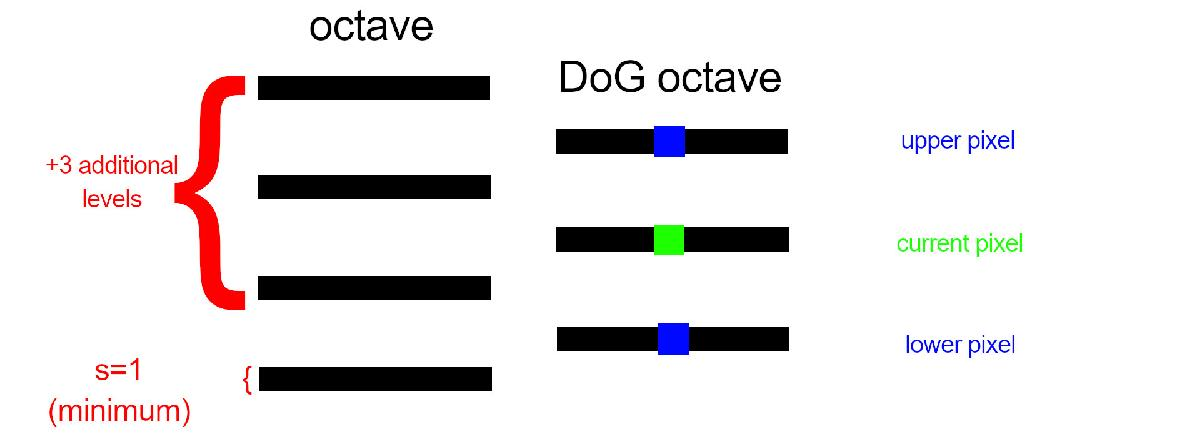

Notice, how in the graphic $s=1$ so we get $s+3=4$ scales for our octave, which yield $4-1=3$ DoGs for that octave. This allows us to approximate the gradient in $\sigma$ direction for $s\;=\;1$ scales because we need an upper and lower DoG for approximation. So at the end of the day, we are able to perform extrema detection in exactly $s$ DoG scales if we generate $s+3$ scales per octave.

We now got a more precise extremum position, now we need to get the more accurate $D$ value at that new position. We can do that with:

### 
$$D(\hat x) = D + \frac{1}{2}\frac{\partial D}{\partial x}^T\hat x$$


There are **some gotchas** that need to be taken care of and that are not mentioned in (1) or (2) explicitly. First, what happens if the offset drives us out of the picture? Remember, we follow the gradient direction to get a new sample point if the absolute value of the gradient in at least one direction is larger than $0\ldotp 5$. That has to be taken care of when programming, and in this case we** just discard the extremum**. Secondly, what happens if our **hessian is ill-conditioned**? We need to build the inverse of our hessian to calculate the offset $\hat{x}$, so that is a problem. It makes sense to discard the extremum in this case, because **an ill-conditioned hessian will result in a very large **$\hat x$** which would probably lie out of the image anyways**.

We also discard those $D(\hat x)$, that lie below a certain threshold `low_cont_thresh` to get rid of low contrast extrema. **The intuition here is that an extremum can be very similar to its surrounding samples but still be the extremum, such cases happen in low contrast areas** (areas of almost similar intensity or almost zero image gradient). Although they are technically extrema, they are of little to no use as features because they can be easily lost when scale, illumination or anything else changes (=** unstable feature**).

The absolute coordinates (coordinates in the original image) will be appended to the extremum $e$ to create a keypoint $k$:


$$k={\left\lbrack x,\;y,\;i,\;j,\;d,{\;x}_a ,y_a ,\sigma \right\rbrack }^T$$


where $x_a$ represents the x position in the original image, $y_a$ represents the y position in the original image and $\sigma$ is our absolute scale position.

What now needs to be implemented is the formula to calculate $\hat x$ and $D\left(\hat{x} \right)$ from above and to filter through our extrema. Here, we will only filter through the extrema of that level and DoG that we visualized in the previous matlab cell. This will make it easier to see the differences after filtering because there are only a few candidates.

% define the threshold for low contrast extremas. Try adjusting the
% threshold if you think too many low contrast keypoints remain. Since we
% scale the new DoGs at the end between 0 and 1, there is a guaranteed
% keypoint remaining (or even more) if you set the threshold to 0.99
low_cont_thresh = 0.7;

% lets use the high_extrema that I already used to visualize the problem
[~, n_high_extrema] = size(high_extrema);
[n_dog_octaves, n_dogs] = size(dogs);

% create a new array to store the more accurate extrema
keypoints = zeros(8, 1);

% the interpolation procedure is restarted a maximum of 5 times at different positions before the
% point is discarded.
max_iter = 5;

% create some counters to count how many features were removed for what
% reason
count_low_contrast = 0;
count_out_of_bounds = 0;

% create a matrix to store all absolute scale positions. If an extremum
% changes scale, we can just look up the index
scale_values = zeros(n_dog_octaves, n_dogs);

% populate the scale value matrix
for i=1:n_dog_octaves
    for j=1:n_dogs
        % calculate the downsampling factor for the i-th octave according
        % to (3)
        ds_factor = 0.5*2^(i-1);
        
        % calculate the scale position for the j-th scale in the i-th
        % octave according to (3)
        scale_value = (ds_factor/0.5)*base_sigma*2^((j-1)/s);
        scale_values(i, j) = scale_value;
    end
end

%iterate through all extrema of that level
for q = 1:n_high_extrema
    % extract the sample point we want to look at
    example_point = high_extrema(:, q);
    
    % extract the coordinates from the sample point
    tmp_cell = num2cell(example_point);
    [x, y, i, j, d] = tmp_cell{:};
    
    
    % helper variable to break outer loop from inner loop
    was_ill_conditioned = false;
    
    % track how many interations were done for the current extremum
    curr_iter = 0;
    
    
    % repeat until gradient is small enough or point drives out of image
    while 1
        
        % we are using the differences of neighboring sample points to approximate
        % the gradient in each direction so lets get the DoG image of our sample
        % point, and the neighboring DoG images in scale space (upper and lower)
        
        % get the DoG images that we need to compute the gradient
        dog = dogs{i, j};
        upper_dog = dogs{i, j+1};
        lower_dog = dogs{i, j-1};
        
        
        % lets compute the gradient
        dD_x = zeros(3, 1);
        
        % for the gradient in scale space direction, we take the difference between the upper
        % and lower pixel.
        dD_x(1) = (upper_dog(x, y) - lower_dog(x, y))/2;
        
        % for the gradient in X direction, we just substract the neighbors
        % in X direction from each other
        dD_x(2) = (dog(x+1, y) - dog(x-1, y))/2;
        
        % same for Y direction
        dD_x(3) = (dog(x, y+1) - dog(x, y-1))/2;
        
        
        % compute the hessian according to (3). Hessians are symmetric so 6
        % entries define the whole matrix
        h11 = upper_dog(x, y) + lower_dog(x, y) - 2*dog(x, y);
        h22 = dog(x+1, y) + dog(x-1, y) - 2*dog(x, y);
        h33 = dog(x, y+1) + dog(x, y-1) - 2*dog(x, y);
        h12 = (upper_dog(x+1, y) - upper_dog(x-1, y) - lower_dog(x+1, y) + lower_dog(x-1, y))/4;
        h13 = (upper_dog(x, y+1) - upper_dog(x, y-1) - lower_dog(x, y+1) + lower_dog(x, y-1))/4;
        h23 = (dog(x+1, y+1) - dog(x+1, y-1) - dog(x-1, y+1) + dog(x-1, y-1))/4;
        
        d2D_x = [h11 h12 h13; h12 h22 h23; h13 h23 h33];
        
        
        % check if the hessian is ill conditioned. stop if this is the case
        % for this, get the absolute value of the determinant
        hessian_det = det(d2D_x);
        tol = 1e-18;
        if abs(hessian_det) < tol
            disp("Hessian was ill conditioned");
            was_ill_conditioned = true;
            break;
        end
        
        % finally we can compute our new position approximation x_hat
        % according to the formula I have shown you
        x_hat = -inv(d2D_x)*dD_x;
        
        % the entries of x_hat are now possibly decimal values we store
        % these very accurate approximations in xa, ya, and ja (ja being
        % the accurate index of the scale)
        
        ja = j + x_hat(1);
        xa = x + x_hat(2);
        ya = y + x_hat(3);
        
        % if we didn't change coordinate, and our new scale lies inside our
        % octave we reached a stable extremum
        if abs(x_hat(2))<0.5 && abs(x_hat(3))<0.5 && abs(x_hat(1))<0.5
            break;
        end
        
        % else, update coordinates for next iteration. Round them because
        % we need integer indices to access our DoGs
        j = round(ja);
        x = round(xa);
        y = round(ya);
        
        % check if new position is actually possible (e.g. not on highest or lowest
        % DoG, not on image edge and also not outside the image
        % get get dimension of the current DoG
        [ih, iw] = size(dog);
        iw = iw-1;
        ih = ih-1;
        n_dogs_max = n_dogs-1;
        % check if the new position is valid
        if x < 2 || x > ih
            % X is out of bounds. set our helper variable to true to signal
            % the outer loop that it is a invalid sample
            was_ill_conditioned = true;
            % break the inner loop
            break;
        end
        if y < 2 || y > iw
            % same for Y
            was_ill_conditioned = true;
            break;
        end
        if j < 2 || j > n_dogs_max
            % same for J
            was_ill_conditioned = true;
            break;
        end
        
        % keep track of iterations for the current extremum. Abort if the
        % maximum is reached
        curr_iter = curr_iter + 1;
        if curr_iter > max_iter
            was_ill_conditioned = true;
            break;
        end
        
        % if it is still in boundaries, the next while iteration is allowed
        % to start.
        
    end

    % discard extrema if something was wrong
    if was_ill_conditioned
        count_out_of_bounds = count_out_of_bounds + 1;
        continue
    end
        
    % at this point we can calculate the new DoG value.
    D_x_hat = d + 0.5 * dD_x.'*x_hat;
    
    
    % our new keypoint will have 3 additional coordiantes:
    % xa, ya and sigma which are the absolute coordinates of the feature
    % remember, we did this whole interpolation to get accurate coordinates
    % on the original picture. xa, ya and ja will not be whole numbers but
    % include fractions, which will increase our accuracy if we scale them
    % up
    
    % get current scale coordinates by rounding accurate coordinates
    x = round(xa);
    y = round(ya);
    
    % compute the more accurate absolute coordinates on original image
    % by multiplying the unrounded coordinates with the downsampling
    % factor and then rounding.
    scale_factor = 0.5*2^(i-1);
        
    xa = floor(xa*scale_factor);
    ya = floor(ya*scale_factor);
    
    % new scale index is just the rounded accurate scale index
    ja = round(ja);
    
    % read sigma for the new scale from array
    sigma = scale_values(i, ja);
    
    % add our new keypoint consisting of 8 coordinates
    new_keypoint = [x, y, i, ja, D_x_hat, xa, ya, sigma].';
    
    keypoints = [keypoints new_keypoint];
    
    
end

% remove our dummy element from the keypoints
keypoints(:, 1) = [];

% last but not least, we need to apply our contrast threshold. Before we can do
% that, we need to scale the new DoG values of all our keypoints in the
% intervall [0 1]
tmp_keypoints = keypoints;
min_DoG_key = min(tmp_keypoints(5, :), [], "all");
tmp_keypoints(5, :) = tmp_keypoints(5, :) - min_DoG_key;
max_DoG_key = max(tmp_keypoints(5, :), [], "all");
tmp_keypoints(5, :) = tmp_keypoints(5, :) / max_DoG_key;

% after normalizing, we check the contrast thresholds.
[~, n_keypoints] = size(tmp_keypoints);
keypoints = zeros(8, 1);
for i = 1:n_keypoints
    % discard the keypoint if the absolute of the new DoG value falls below
    % our threshold. To do this, I only add keypoints that are above the
    % threshold
    if abs(tmp_keypoints(5, i)) > low_cont_thresh
        keypoints = [keypoints tmp_keypoints(:, i)];
    end
end


% plotting (NOT PART OF SIFT)
% this code filters through the accuracy adjusted extremas and removes
% those, that changed level (or scale)
keypoints_this_level = zeros(8, 1);
[~, n_new_high_extremas] = size(keypoints);
for i=1:n_new_high_extremas
    if keypoints(4, i) == 2
        keypoints_this_level = [keypoints_this_level keypoints(:, i)];
    end
end
keypoints_this_level(:, 1) = [];

func_plot_after_accu(high_extrema, scaled_high_extrema, keypoints_this_level, high_sspace_transformed, I_original);

The red crosses represent the remaining keypoints of this scale, the green squares represent the extrema from earlier. There are multiple cases visible:

- The **red cross is exactly in the center of the green square**: in this case, the extremum was already at the right position.

- The **red cross has moved from the green square**: in this case, the accuracy adjustment followed the laplacian to find a more accurate extremum

- There is **no red cross for a green square**:  this can happen due to **3 different reasons**: **1.** the extrema was a low-contrast extrema and got discarded, **2.** the new more accurate extremum lies out of the image or octave so the extremum got discarded or **3.** the more accurate extremum lies on a different scale and was moved to that scale (we only consider and show one scale here for clarity)

Notice how more red crosses changed position in the original image plot (right) because of the added accuracy. This effect is especially visible at the vertical bar to the left in the background. We were able to restore the position from the upscaled version (left, higher space-scale), or more precicely from our laplacian approximation. If there were extrema near the border, you could also see how the extrema that were created from the black border (convolution artifact) were removed since their approximated gradient *moved* them out of the image.

### Removing edge responses

The next refinement step is to remove edge responses (keypoints that lie on an edge, not a corner). The lecture already motivated why you would want to do that. **The way SIFT does this is actually in a similar way as we have seen in the Harris detector**. **Both make use of the fact that the Harris matrix **$H$** has two positive eigenvalues at a corner**. The difference is though, that SIFT uses the hessian $H_e$ (second derivatives) whereas Harris uses a multiplication of gradients (Harris matrix $H_a$). First, calculate the hessian matrix $H_e$ and **use the determinant and trace to detect if a keypoint is an edge or corner**. SIFT doesn't use the harris criterion but directly compares the ratio of the two eigenvalues $\lambda_{\max }$ and $\lambda_{\min }$ which can be achieved without explicitly calculating these (for computational efficiency). The **criterion used by SIFT** is according to (1) and (3):

### 
$$\frac{Tr(H_ e)^2}{Det(H_e)}=\frac{(\lambda_{max} + \lambda_{min})^2}{\lambda_{max} \lambda_{min}} < \frac{(C_{edge} + 1)^2}{C_{edge}}$$


**If this condition is not fulfilled, SIFT discards the keypoint**. To see the similarity, here again the **harris criterion** according to the lecture slides:

### 
$$h = Det(H_a) - k(Tr(H_a))^2$$


For both you need to define a scalar ($C_{\textrm{edge}}$for SIFT and $k$ for Harris) that weigh how *edgy *and edge has to be. For the sake of clarity, this is again only done for one scale of one octave:

% define C_edge that determines how edgy an edge has to be. Feel free to
% play around with it. The smaller c_edge, the stricter the edge check and
% the less final keypoints.
c_edge = 10;

% create an array to hold the keypoints after this final refinement step
final_keypoints = zeros(8, 1);

% we again only do it for a specific scale (level), the one we also used for
% accuracy enhancement.
[~, n_keypoints] = size(keypoints_this_level);

for q = 1:n_keypoints
    % get the indices for the corresponding DoG
    
    tmp_cell = num2cell(keypoints_this_level(:, q));
    [x, y, i, j, d, xa, ya, sigma] = tmp_cell{:};
    
    % get the dog
    dog = dogs{i, j};
    
    % compute the hessian matrix by using difference of neighbours according
    % to (3)
    h11 = dog(x+1, y) + dog(x-1, y) - 2*dog(x, y);
    h22 = dog(x, y+1) + dog(x, y-1) - 2*dog(x, y);
    h12 = (dog(x+1, y+1) - dog(x+1, y-1) - dog(x-1, y+1) + dog(x-1, y-1))/4;
    H = [h11 h12; h12 h22];
    
    % skip features with a negative hessian determinant (non-corners)
    h_det = det(H);
    if h_det < 0
        continue
    end
    
    % compute edginess according to the formula shown above
    edginess = trace(H)^2/det(H);
    
    threshold = (c_edge + 1)^2/c_edge;
    
    % add to final keypoints if edginess is below threshold
    if edginess < threshold
        final_keypoints = [final_keypoints keypoints_this_level(:, q)];
    end
end

% remove dummy element
final_keypoints(:, 1) = [];


% aaaand again, plot the difference (not part of SIFT)
func_plot_after_edges(final_keypoints, keypoints_this_level, high_sspace_transformed, I_original);

The remaining keypoints are shown as red crosses.The effect of this refinement is not that special. You should notice that obvious edge points were discarded.

Keep in mind that those are still not the features that SIFT will output. There are still steps to be done and shown here are only the features of a single scale.

### SIFT detector controls at your hand

To conclude the detector part of SIFT, we mash all the previous steps into a single `func_SIFT` function that calls the previous steps one after another. You are now able to play around with all detector parameters to see how it affects the detected keypoints and compare it to Matlabs Harris detector. This cell will also generate some statistics that indicate how many extrema were removed for what reason and how the remaining extrema are distributed along the octaves. I will also clean up the workspace because it has gotten pretty full.

% clear everything from workspace but keep the image we have loaded
clearvars;

% select a different image if you want. If you use one of your own, make
% sure it is of reasonable size, e.g. under 1000 px in width and height
file_name = "lenna.tif";
I = im2double(rgb2gray(imread(file_name)));

% All controls of SIFT at your hand

% origin in scale space
% 0.8 is the default value
base_sigma = 0.8;

% number of octaves to compute (computationally expensive!)
% 4 is the default value
n_octaves = 4;

% number of scales to comput, 3 are added ontop (computationally
% expensive!)
% 5 is the default value
s = 5;

% threshold for edginess. The lower, the more edges are removed
% 10 is the default value
c_edges = 10.3;

% max retries for laplace approximation. (a bit expensive if too high)
% 5 is the default value
max_iter = 5;

% contrast threshold to deal with low contrast keypoints
% 0.7 is the default value
contrast_threshold = 0.7;

% adapt filter size (computationally expensive!)
% this is a tradeoff: adapting the size gives more (potentially better)
% features but increases computation time by a lot.
adapt_filter_size = true;


% sift (our implementation)
[keypoints, ~, ~, extrema, cr_edge, cr_contrast, cr_oob] = func_SIFT(I, ...
    base_sigma=base_sigma, n_octaves=n_octaves, s=s, c_edges=c_edges, max_iter=max_iter, ...
    contrast_threshold=contrast_threshold, adapt_filter_size=adapt_filter_size);

% harris (CV-toolbox)
harris_extremas = detectHarrisFeatures(I);

figure('position', [0, 0, 1200, 500]);
colormap("gray");
subplot(1, 2, 1);
imshow(I, []);
title("SIFT");
axis equal;
hold on;
% plot all found features of all scales in one x-y plane
plot(keypoints(7, :), keypoints(6, :), '+g');
hold on;
subplot(1, 2, 2);
imshow(I, []);
title("Harris");
axis equal;
hold on;
% plot all found harris features
plot(harris_extremas);
% plot some useful statistics
func_generate_statistics(n_octaves, extrema, keypoints, cr_edge, cr_contrast, cr_oob);

### Key observations:

- the **contrast threshold is by far the main reason for feature removals**. This also makes it one of the **most important hyperparameters** 

- the **number of keypoints per octave falls off per octave**. This is expected for a typical image, since there are likely much more fine details than bigger structural details

- a **high base sigma will completely ignore fine details** (as we start with a substantial smoothing in scale space)

- **not every octave has to include keypoints**. You can go *too high* in scale space and won't find any keypoints there simply because the image doesn't have very basic structural features.

- **adapting the filter size has a big impact on computation time and feature quality**, especially if you reach high scale space positions

- for `s=1` and `n_octaves=1`, we basically sample only at the original image. Notice how in this case, the major removal reson is out of image. That happens because a lot of features belonged to a higher scale and thus were removed. SIFT is not designed to work with such a parameter configuration

- compared to Harris, SIFT can be tweaked towards the kind of features (structural, fine) you are interested in

## SIFT Step 3: Keypoint Descriptor

*The remaining steps of SIFT technically are not part of the feature detection, but rather of the feature description. I will not go into detail for them, since they go beyond the assignment task.*

So far our keypoints provide scaling invariability (*zooming out*). It would also be nice to have rotation and illumination invariance, so features can be matched even if the image is rotated and lighting conditions change. Our current keypoint $k$ with it's position coordinates and scale value won't be sufficient for that, we will need to append some more entries to it which provide a description that is invariant to rotation and illumination.

**You can achieve rotation and illumination invariance by using the normalized image gradient**, which is also shown in the lecture slides 1.4. **The main idea is, that the gradient direction does not change with illumination changes and the gradient magnitude does not change with rotation changes**. Thus, if you normalize the gradient magnitude and align the gradient directions, you have rotation and illumination invariance (in theory). So ultimately, we want to compute some metrics out of the image gradients and append them to our keypoint $k$ to have a nice description of the keypoint with rotation and illumination invariance. Like all things in SIFT, it is of course a little more involved and sophisticated than simply appending the gradient orientation and magnitude to $k$.

**We start by computing the image gradients in x and y direction for each scale in each octave**. Like in HW1, we use the sobel filter, so I won't go into detail here. In (2) and (3), the authors use the difference of neighbors again to approximate the gradient. They claim, that due to the substantial scale smoothing, the approximation is good enough. When testing however, I have observed that the sobel gradient significantly outperforms the difference of neighbors in terms of gradient orientation approximation.

Lets implement the gradient calculation:

% clear workspace again
clearvars;
% load lenna again
I_original = rgb2gray(imread("lenna.tif"));
I = im2double(I_original);

% run sift with default parameters
[intermediate_keypoints, octaves, dogs] = func_SIFT(I);

%%%%% Compute gradients
% get the size of our current scale space
[n_octaves, n_scales] = size(octaves);

% create two cells: the first holding our gradients in x direction and the
% second our gradients in y direction
dx_octaves = cell(n_octaves, n_scales);
dy_octaves = cell(n_octaves, n_scales);

% define sobel kernels
x_kernel = double([-1, 0, 1; -2, 0, 2; -1, 0, 1]);
y_kernel = double([-1, -2, -1; 0, 0, 0; 1, 2, 1]);

% iterate through each octave
for i=1:n_octaves
    % iterate through each scale
    for j=1:n_scales
        % get the current scale that we want to differentiate
        curr_scale = octaves{i, j};
        
        % compute gradient in x and y direction
        dx_octaves{i, j} = conv2(curr_scale, x_kernel, 'same');
        dy_octaves{i, j} = conv2(curr_scale, y_kernel, 'same');
    end
end

### Keypoint reference orientation

SIFT now uses these gradients to calculate a reference orientation $\theta_{\textrm{ref}}$ for each keypoint. To get a more stable orientation, SIFT combines the keypoint gradient with the gradient of neighboring pixels. All these gradients are collected in a histogram which will peak at the most common orientations. These orientations are then selected as $\theta_{\textrm{ref}}$ , which means that a single keypoint can have multiple reference orientations. To summarize, we will need to do the following things for each keypoint:

- get the neighborhood of our keypoint. The size of the neighborhood is scaled with $\lambda_{\textrm{ori}}$ and the scale $\sigma$ of the feature

- compute a weighted gradient magnitude and the gradient orientation for each pixel in the neighborhood

- put the weighted gradient magnitude in a discretized histogram. The position in the histogram is determined by the gradient orientation

- smooth the histogram

- pick the orientations that go above a certain threshold in the histogram as $\theta_{\textrm{ref}}$

Gradient magnitudes are weighted by a 2D gaussian filter with standard deviation of $\lambda_{\textrm{ori}} \sigma$. 

The features will be reduced to:


$$f=\left\lbrack i,j,x_a ,y_a ,\sigma \right\rbrack$$


Where $i$ is the octave index, $j$ is the scale index, $x_a$ and $y_a$ are the absolute feature positions on the original image and $\sigma$ is the feature scale. Along with the features, `func_keypoint_orientation` returns the reference orientations for each keypoint in `theta_refs`. Those are `n_bins` by 1 column vectors of zeros that are non-zero at the bin of the reference orientation. 

% lambda ori will determine our patch size.
lambda_ori = 1.5;

% n_bins will determine the amount of bins in our histogram.
% setting it to 36 will result in 36 bins for 360° so each bin will hold a
% range of 10°
n_bins = 36;

% threshold for reference orientations
t = 0.8;

% have a look at the function if you are interested, I wont go into detail
% because the function is quite long and is not part of the feature
% detector but rather the feature descriptor. This livescript also is
% already quite long
[intermediate_features, theta_refs, grad_hists, n_removed] = func_keypoint_orientation(intermediate_keypoints, ...
    octaves, dx_octaves, dy_octaves, lambda_ori, n_bins, t, 0.8);
% plot the gradients
func_plot_orientations(I_original, intermediate_features, theta_refs);

Some keypoints have more than one orientation, some were too close to the border so SIFT discarded them. Each keypoint has at least one line going away from them, pointing in the direction of the reference gradient. These lines are not adapted to the gradient magnitude, they just indicate the orientation! **Some orientations might seem to be slightly off but remember that they are an average of all neighboring gradients, not the gradient at the exact feature position!**

### Keypoint descriptor construction

For me, this was not very straight forward and implementing it was neither. The main idea for the SIFT descriptor is to describe the local region around each feature with measures that are invariant to rotation, translation, scaling and illumination changes. How does SIFT achieve each attribute?

- rotation invariance: use normalized gradient orientations (we already have this)

- translation invariance: don't use pixel coordiantes to describe a feature, describe the local neighborhood

- scaling invariance: have features at different scale-space positions (we already have this)

- illumination invariance: use normalized gradients

The SIFT descriptor will sample the gradients of neighboring pixels and weigh them by the distance to the feature. It then creates a grid of size $n_{\textrm{hist}} \times n_{\textrm{hist}}$ orientation normalized histograms and fills these with the nearest neighbor gradients. Each histogram has `n_ori` bins to discretize the orientations. SIFT then stacks all histograms to create a column vector of size $n_{\textrm{hist}} n_{\textrm{hist}} n_{\textrm{ori}} \times 1$ which will be our final descriptor for each feature. The neighborhood size is scaled with $\lambda_{\textrm{descr}}$ and the feature scale sigma to focus on a larger or smaller neighborhood for each descriptor.

The detailed algorithm is found in (3) and I also left some comments in the respective function `func_keypoint_descriptor`. Feel free to have a look at it, but it is not essential to understand the SIFT feature detection part. We will, however, later use it for feature matching.

% number of histograms
n_hist = 4;

% number of bins per histogram
n_ori = 8;

% scaling of gaussian window
lambda_descr = 6;

[descriptors, features, n_skipped] = func_keypoint_descriptor(intermediate_features, theta_refs, I, ...
    dx_octaves, dy_octaves, n_hist, n_ori, lambda_descr);


In (4), you can see how these histograms look like but I won't generate fancy plots here to reduce the size of this livescript.

## SIFT Step 4: Feature matching

Because the SIFT descriptor performs so much work to build a feature vector of invariant measures, the feature matching boils down to just finding the lowest euclidean distance between two descriptors. Along with the features and descriptors for both images, the feature matcher takes the optional arguments $C_{\textrm{rel}\;\textrm{match}}$ and $C_{\textrm{abs}\;\textrm{match}}$. Two descriptors  $d_a$ and $d_b$ are matched if the two conditions are met:

### 
$$||d_a -d_b ||<C_{\textrm{abs}\;\textrm{match}}$$


### 
$$||d_a -d_b ||<C_{\textrm{rel}\;\textrm{match}} ||d_a -d_{b^{\prime } } ||$$


where $d_{b^{\prime } }$ is the descriptor with the second smallest distance to $d_a$. The first condition makes sure, that a match can't be made from descriptors that are arbitrarily distant from each other. The second makes sure that the distance of the match is significantly smaller than the second best match. This is useful if for example two very similar descriptors are found. You can't really tell which one is right because both are very close, so rather than outputting a potential false-positive, you decide to ignore this match.

The implementation is found in `func_SIFT_matcher` and is not further described here, as it is pretty simple and not part of the feature detector. As a first showcase, I let SIFT match features between an image and its 90° rotated version. I created a new function called `func_SIFT_with_descriptor` which runs the full SIFT algorithm (detector+descriptor) and returns the descriptors as first output and the corresponding features as second output.:

% select image one
img1 = I;
% run SIFT. d1 contains the descriptors, f1 contains the features
[d1, f1, ~] = func_SIFT_with_descriptor(img1);

% select image two
img2 = imrotate(I, 90);
% run SIFT for image two
[d2, f2, ~] = func_SIFT_with_descriptor(img2);

% run SIFT matching
[matches, descriptor_matches] = func_SIFT_matcher(f1, f2, d1, d2);

% plot matches.
func_plot_matches(matches, img1, img2, "SIFT Matching");

Great! Seems like SIFT is working reasonably well, at least for this example. **Our SIFT implementation is now finished and we can start comparing it to Harris!**

## Comparison: SIFT vs Harris

It's time to see how our SIFT implementation performs against Matlabs Harris implementation. The following points will be compared:

- Speed: which algorithm is faster?.

- Complexity: how hard is it to implement?

- Feature quality: why can a BLOB be a better feature than a corner?

- Feature matching: some example problems to compare matching performance

### Speed

This is fairly obvious and you might have already noticed it. **SIFT is comparably slow** (especially this unoptimized extremely slow implementation, I hope your PC didn't die yet) (4). If you think about it, the only computationally expensive task for Harris is the convolution operation to get the image gradients (and maybe the per-pixel calculation of the harris criterion). Just by knowing how the scale-space for SIFT is constructed, it is already clear that **SIFT will take longer (because it needs to convolve multiple times)**, no matter how far you optimize it. Even if you select `n_octaves = 1` and `s=1` you are still doing $s+3=4$ convolution operations just to construct the scale-space compared to the $2$ convolution operations for Harris to get the image gradients. **The local extrema detection and local laplacian approximation are also two important compute time cost factors which do not exist for Harris**. For the sake of giving you numbers, lets just measure the time by running each algorithm for 10 times and averaging over the time needed. For fairness, we use `func_SIFT` instead of `func_SIFT_with_descriptor` because Harris doesn't have a built-in descriptor. SIFT hyperparameters that have a great influence on computation time can be adjusted via a slider.

**Warning: Cranking up all sliders needs a very performant PC or a lot of your time**

% how many times to run
n_times = 10;
% store times
times = zeros(2, n_times);

% SIFT parameters (lower base_sigma = faster)
speedtest_base_sigma = 10;
% octave count (lower = faster, fastest for n_octaves=1)
speedtest_n_octaves = 1;
% s (lower = faster, fastest for s=1)
speedtest_s = 1;
speedtest_c_edges = 10;
% we also use lowest possible reiteration count for laplacian approx.
% (lower = faster, fastest for max_iter=1)
speedtest_max_iter = 1;
% adapt filter size. This will adapt the convolution filter size to each scale. In
% higher scales, a larger filter will significantly increase computation
% time
% (fastest when false, slow when true)
speedtest_adapt_filter = false;
speedtest_contrast_threshold = 0.7;

% run both multiple times
for i=1:n_times
    tic
    detectHarrisFeatures(I);
    times(1, i) = toc;
    
    tic
    func_SIFT(I, ...
        base_sigma=speedtest_base_sigma, ...
        n_octaves=speedtest_n_octaves, ...
        s=speedtest_s, ...
        c_edges=speedtest_c_edges, ...
        max_iter=speedtest_max_iter, ...
        contrast_threshold=speedtest_contrast_threshold, ...
        adapt_filter_size=speedtest_adapt_filter);
    times(2, i) = toc;
end

avg = mean(times.');
labels = {'Harris', 'SIFT'};
figure;
bar(avg);
ylabel("Average computation time in seconds");
title("Computation time Harris vs SIFT")
set(gca, 'xticklabel', labels);

You might already know what that means: SIFT is not the best choice for realtime applications with limited computation power. For tracking an object location in a video stream you would want a computation time well below 1 second to be able to process more than one image per second (usually video streams come in at 24, 30 or even 60 FPS).

**In practice, it might not be that bad**: consider that (a) **my SIFT implementation is not optimized in any way** and (b) we live in a time where **mobile GPUs are a thing and those can accelerate all these convolutions significantly**. If a device can process videos in real-time with a neural network it should also be able run SIFT in real-time. The SIFT implementation of (4) is already at under 0.2 seconds.

### Complexity

This is a measure often overlooked by people who don't have to implement the algorithm themselves. But if you need to choose an algorithm for your task, you also want to take into account how much effort it is to implement. This again is not a measure where SIFT shines and Harris is definitely easier. **In my opinion, SIFT bridges the gap between *****traditional***** computer vision algorithms and *****convolutional neural networks (CNNs)***** in terms of complexity**. It is like a traditional CV method since it doesn't *learn* or *adapt *but at the same time it creates this layer by layer approach that you also see in CNNs. Performing the rather complex local extrema search in this 3D layer stack and fitting a 3D function to interesting points definitely goes into the direction of neural networks. There is no plot to show here and this measure is subjective but after going through the implementation together, I think you will agree that **SIFT is more complex than Harris**.

### Feature quality: BLOBs

This is SIFTs time to shine. Let me first clarify something: **both algorithms (SIFT and Harris) detect corners**. But as Harris only uses the Harris criterion, SIFT finds extrema in scale-space, discards low-contrast extrema and then applies a Harris-like criterion to distinguish between edges and corners. **Because SIFT uses the scale-space, it can also detect so-called "Blobs"**. A Blob in general is a region where the image properties differ significantly which makes it a good candidate for a feature. In the original image, a Blob might be corner-less but can transform into something with corners in higher scale-space.

Let me show you why this is useful by using a toy example. The setting is that we want to find features that best describe a black circle against a white background:

% load example image
qtest_I = imread("black_circle.png");
qtest_I = rgb2gray(qtest_I);
qtest_I_original = double(qtest_I);
% normalize
qtest_I = qtest_I/max(max(qtest_I_original));

% run SIFT
[qtest_sift_keypoints, qt_octaves, qt_dogs] = func_SIFT(qtest_I, base_sigma=16);
% run Harris
qtest_harris_keypoints = detectHarrisFeatures(qtest_I);

figure('position', [0, 0, 1200, 500]);
colormap("gray");
subplot(1, 2, 1);
image(0, 0, qtest_I_original);
title("SIFT");
axis equal;
hold on;
% plot all found features of all scales in one x-y plane
plot(qtest_sift_keypoints(7, :), qtest_sift_keypoints(6, :), '+g');
hold on;
subplot(1, 2, 2);
image(0, 0, qtest_I_original);
title("Harris");
axis equal;
hold on;
% plot all found harris features
plot(qtest_harris_keypoints);

What feature would you use to describe the location of a circle efficiently? Is it the center point? Great, because exactly that is what SIFT also found. Notice how Harris - limited to it's corner criterion - wildly detects points on the border of the circle that arise because of discretization. This is a prime example how SIFT can detect Blobs, in our case, the whole circle is a Blob and SIFT found a good feature for it.

But how did SIFT do it? Well, I gave it a little push to focus on more structural features by giving it a large `base_sigma` of 16 (which is 20 times the default sigma). This means that we start at a very high point in scale-space for our first octave and go even higher. At some scale, the smoothing is strong enough to collapse the whole circle to a central point and have a gradient going outwards. Let's actually plot the scale at which SIFT found this feature along with the DoG, then it is obvious how SIFT found it:

% unpack the coordinates
tmp_cell = num2cell(qtest_sift_keypoints(:, 1));
[qt_x, qt_y, qt_i, qt_j, qt_d, qt_xa, qt_ya, qt_sigma] = tmp_cell{:};

% resize factor
qt_resize = 0.5*2^(qt_i-1);
% get corresponding image
qt_image = imresize(qt_octaves{qt_i, qt_j}, qt_resize, "bilinear");
qt_dog = imresize(qt_dogs{qt_i, qt_j}, qt_resize, "bilinear");
% plot
figure('position', [0, 0, 1200, 500]);
colormap("gray");
subplot(1, 2, 1);
imshow(qt_image, []);
title("Scale of feature");
axis equal;
hold on;
plot(qtest_sift_keypoints(7, :), qtest_sift_keypoints(6, :), '+g');
hold on;
subplot(1, 2, 2);
imshow(qt_dog, []);
title("DoG of feature");
axis equal;
hold on;
plot(qtest_sift_keypoints(7, :), qtest_sift_keypoints(6, :), '+g');

The circle collapsed to a single extremum in the middle of the DoG image, which SIFT of course found. Of course, this doesn't proof that SIFT will always find such nice features, but at least it has the possibility to do so, compared to Harris. The main purpose of this example is to show you what scale-space representations can do for you and how they improve feature quality.

But is it actually usefull when it comes to matching? Let's do a very simple thing and rotate the circle. We then try to match features from the original image to the rotated version. A circle is rotation invariant and so should be its features. Try moving the slider and watch how reliably SIFT matches the Blob feature compared to Harris and its corner features:

% rotation angle in degrees
rot_angle = 72;

% load example image
qtest_I = imread("black_circle.png");
qtest_I = rgb2gray(qtest_I);
qtest_I_original = double(qtest_I);
qtest_I2_original = imrotate(qtest_I_original, rot_angle);
% normalize
qtest_I = qtest_I_original/max(max(qtest_I_original));
qtest_I2 = qtest_I2_original/max(max(qtest_I2_original));

% run SIFT on both
[d1, f1, ~] = func_SIFT_with_descriptor(qtest_I, base_sigma=16, lambda_ori=0.5, lambda_descr=0.5);
[d2, f2, ~] = func_SIFT_with_descriptor(qtest_I2, base_sigma=16, lambda_ori=0.5, lambda_descr=0.5);
[matches, ~] = func_SIFT_matcher(f1, f2, d1, d2);

% run Harris on both
ph1 = detectHarrisFeatures(qtest_I);
ph2 = detectHarrisFeatures(qtest_I2);


func_plot_matches(matches, qtest_I, qtest_I2, "SIFT");
func_plot_harris_matches(ph1, ph2, qtest_I, qtest_I2, "Harris");

Around multiples of $\pi$, Harris at least finds some matches, but those include a lot of false positives. At this point, Harris is basically just guessing and matching discretization artifacts. SIFT on the other hand, reliably matches the circle center, no matter the rotation (= rotation invariant feature).

You might have noticed that I changed $\lambda_{\textrm{ori}}$ and $\lambda_{\textrm{descr}}$. Remember that those and the feature sigma are used to scale the neighbor region that is considered when building the descriptor. Why does it have to be so small here? Well, our circle center feature lies pretty high in scale space, which means that the neighbor region will be large (because we have a large sigma). If this region goes out of the image, the descriptor discards the feature. To avoid that, we artificially shrink the neighborhood size with a small $\lambda_{\textrm{ori}}$ and $\lambda_{\textrm{descr}}$, so our feature is not discarded. This is important to know when you expect SIFT to work mainly in a high scale-space realm.

### Feature quality: Rotation, Scaling & Noise

Let's see **how consistent the number of SIFT features are compared to Harris features**, as this is also a measure for feature quality. We will go back to our standard test image to compare the two, for fairness sake. There is of course hardly any general statement possible since it highly depends on the image. Before you get any sliders, I will first let SIFT and Harris run on images that are incrementally rotated, scaled and corrupted with noise and plot how many features were found each time. **Ideally, we want a consistent number of features no matter the effect applied**.

This cell will take a while to finish (because of my shitty optimization) so feel free to get a coffee in the meantime.

% clear workspace
clear;

% load lenna
I_original = rgb2gray(imread("lenna.tif"));
I = im2double(I_original);

% create an array to hold the number of features found per algorithm per
% rotation. We will use 20 degree increments
n_rot_features = zeros(2, 18);
% iteratively rotate image and run both algorithms
I_tmp = I;
for i=1:18
    [f_SIFT, ~] = func_SIFT(I_tmp);
    f_HARRIS = detectHarrisFeatures(I_tmp);
    I_tmp = imrotate(I, 20*i);
    [~, n_f_SIFT] = size(f_SIFT);
    [n_f_HARRIS, ~] = size(f_HARRIS);
    n_rot_features(1, i) = n_f_SIFT;
    n_rot_features(2, i) = n_f_HARRIS;
end

% create an array for scaling
n_scale_features = zeros(2, 5);
I_tmp = I;
for i=1:5
    [f_SIFT, ~] = func_SIFT(I_tmp);
    f_HARRIS = detectHarrisFeatures(I_tmp);
    if i==5
        break;
    end
    I_tmp = imresize(I, 1 - 0.2*i);
    [~, n_f_SIFT] = size(f_SIFT);
    [n_f_HARRIS, ~] = size(f_HARRIS);
    n_scale_features(1, i) = n_f_SIFT;
    n_scale_features(2, i) = n_f_HARRIS;
end

% create an array for noise
n_noise_features = zeros(2, 10);
I_tmp = I;
for i=1:10
    [f_SIFT, ~] = func_SIFT(I_tmp);
    f_HARRIS = detectHarrisFeatures(I_tmp);
    I_tmp = imnoise(I, "gaussian", 0, i*0.01);
    [~, n_f_SIFT] = size(f_SIFT);
    [n_f_HARRIS, ~] = size(f_HARRIS);
    n_noise_features(1, i) = n_f_SIFT;
    n_noise_features(2, i) = n_f_HARRIS;
end

x_rot = linspace(0, 340, 18);
x_scale = linspace(1, 0.2, 5);
x_noise = linspace(0, 0.09, 10);

figure("Position", [0, 0, 2000, 500]);
subplot(1, 3, 1);
plot(x_rot, n_rot_features(1, :), x_rot, n_rot_features(2, :));
ylabel('Number of features');
xlabel('Rotation in degrees');
legend('SIFT', 'Harris');
title('Rotation');

subplot(1, 3, 2);
plot(x_scale, n_scale_features(1, :), x_scale, n_scale_features(2, :));
set(gca, 'xdir', 'reverse');
ylabel('Number of features');
xlabel('Scale factor');
legend('SIFT', 'Harris');
title('Scaling');

subplot(1, 3, 3);
plot(x_noise, n_noise_features(1, :), x_noise, n_noise_features(2, :));
ylabel('Number of features');
xlabel('Noise variance');
legend('SIFT', 'Harris');
title('Noise');

Looking at rotation, we see that Harris is more consistent, although it also fluctuates quite a lot. Remarkable is the peak at 0° and 180° rotation for SIFT. SIFT and Harris show significant drops in feature count for 45°, 135° and 225°. An explanation might be that at these angles, the amount of black area around the images is maximized which has a negative influence on the feature count.

In terms of scaling, SIFT also has a steeper slope, so loses more features per scaling step. However, the absolute amount of features is constantly above the amount of Harris features, which is probably the reason for SIFTs superior performance in scaling matching (more on that later).

Noise is pretty interesting. It is reasonable that the feature count increase for both, since the added noise introduces a lot of false corners and extrema. Notice how Harris instantly makes a large jump in feature count and stays almost constant after that. This can be an indication that even the slightest noise already caused Harris to lose all features that were related to the original image. SIFT seems a little more resistive against lower noise counts. This is expected, since the smoothing that is done in scale-space has a regulatory effect on the noise and helps to surpress noise-induced extrema for moderate noise levels. Unfortunately this effect is also limited and can't compensate for noise with larger variances.

In conclusion: Harris is more consistent w.r.t. rotation and scaling, SIFT w.r.t. noise. Keep in mind that this is no indication for matching performance yet, we can just draw some mild conclusions (e.g. non of them will match anything at 0.2 scaling).

If you want to get a better feeling of how the features change, feel free to play with the following cell:

% clear workspace
clear;

% scaling factor
scaling_factor = 1;

% rotation angle
rotation_angle = 0;

% noise variance
noise_variance = 0.01;

% load lenna
I_original = rgb2gray(imread("lenna.tif"));
I = im2double(I_original);
I = imrotate(imnoise(imresize(I, scaling_factor), "gaussian", 0, noise_variance), rotation_angle);

% run sift and harris
[f_SIFT, ~] = func_SIFT(I);
f_HARRIS = detectHarrisFeatures(I);

% plot result
figure('position', [0, 0, 1200, 500]);
colormap("gray");
subplot(1, 2, 1);
imshow(I, []);
title("SIFT");
axis equal;
hold on;
% plot all found features of all scales in one x-y plane
plot(f_SIFT(7, :), f_SIFT(6, :), '+g');
hold on;
subplot(1, 2, 2);
imshow(I, []);
title("Harris");
axis equal;
hold on;
% plot all found harris features
plot(f_HARRIS);

### Feature matching: Where is Waldo?

You might recognize this popular game for kids, where you need to find a person called waldo or wally in a crowded picture. Using a reference picture, this can of course also be played by SIFT and Harris. To make it even more competitive,** this cell will first show you a reference picture of Waldo (in the top right corner) and the image with waldo in it somewhere. It will automatically start SIFT and you can try if you are able to find Waldo before SIFT does. This DOESN'T WORK when using Matlab Online since the output there is only returned when the complete cell is finished.**

% clear workspace
clearvars;

I_waldo = imread("waldo_referenz.png");
I_waldo = rgb2gray(I_waldo);
I_waldo_original = double(I_waldo);
I_waldo = I_waldo_original - min(I_waldo_original, [], "all");
I_waldo = I_waldo/max(I_waldo, [], "all");

I_suchbild = imread("waldo_suchbild.jpg");
I_suchbild = rgb2gray(I_suchbild);
I_suchbild_original = double(I_suchbild);
I_suchbild = I_suchbild_original - min(I_suchbild_original, [], "all");
I_suchbild = I_suchbild/max(I_suchbild, [], "all");


[h1, w1] = size(I_waldo);
[h2, ~] = size(I_suchbild);
padded_img1 = zeros(h2, w1);
padded_img1(1:h1, :) = I_waldo;
im = [I_suchbild, padded_img1];
figure;
colormap("gray");
imshow(im, []);
title("Where is Waldo?");



% run sift on both images
[d1, f1, ~] = func_SIFT_with_descriptor(I_waldo);
[d2, f2, ~] = func_SIFT_with_descriptor(I_suchbild);

% run SIFT matching
[matches, ~] = func_SIFT_matcher(f1, f2, d1, d2);

% plot the result
func_plot_matches(matches, I_waldo, I_suchbild, "SIFT: Where is Waldo?");

% run Harris matching
p1 = detectHarrisFeatures(I_waldo);
p2 = detectHarrisFeatures(I_suchbild);
[fh1, vp1] = extractFeatures(I_waldo, p1);
[fh2, vp2] = extractFeatures(I_suchbild, p2);
indexPairs = matchFeatures(fh1, fh2);
matchedPoints1 = vp1(indexPairs(:, 1),:);
matchedPoints2 = vp2(indexPairs(:, 2),:);
harrisMatches = zeros(10, 0);
[n_matches, ~] = size(indexPairs);
if n_matches == 0
    % no matches found
    disp("WARNING: Harris couldn't find any matches!");
    func_plot_matches([], I_waldo, I_suchbild, "Harris: Where is Waldo?");
else
    % transform features
    for i = 1:n_matches
        p1 = matchedPoints1(i).Location;
        p2 = matchedPoints2(i).Location;
        p1 = round(p1);
        p2 = round(p2);
        
        new_match = zeros(10, 1);
        new_match(3) = p1(2);
        new_match(4) = p1(1);
        new_match(8) = p2(2);
        new_match(9) = p2(1);
        harrisMatches = [harrisMatches new_match];
    end
    harrisMatches(:, 1) = [];
    func_plot_matches(harrisMatches, I_waldo, I_suchbild, "Harris: Where is Waldo?");
end

As you can see, Harris is not able to find Waldo but SIFT is. This is supposedly an easy example because **there is no scaling, rotation, shearing or illumination change**. Waldos head is just translated. Depending on how fast your PC is, you probably found Waldo before SIFT finished. **The advantage that SIFT has over Harris is that each feature is described also by it's local neighborhood which provides a distinctive description.** This is a big advantage in a very crowded image (SIFT found the correct matches from over 16000 features of the big picture). **Harris fails because it's "descriptor" (consisting only of the pixel coordinates) is not descriptive enough** to distinguish Waldos features from the large amount of features found in the big picture (over 15000).

### Feature matching: Scaling

In (4) - the paper also referenced in the assignment task description - SIFTs performance is compared to other detectors for various image transformations. Since I especially advertised invariance wrt scaling and it's also embedded in SIFTs name, I made a cell to compare feature matching to Harris for various scaling factors. Try moving the slider to run the cell for different scaling factors and compare it to Harris performance:

% clear workspace
clearvars;

scale_factor = 0.5;

% load the image of the car front
img_1 = im2double(rgb2gray(imread("mercedes_front_b.png")));

% second image is a scaled down version
img_2 = imresize(img_1, scale_factor);

% run SIFT and plot result
[d1, f1, ~] = func_SIFT_with_descriptor(img_1);
[d2, f2, ~] = func_SIFT_with_descriptor(img_2);
[matches, ~] = func_SIFT_matcher(f1, f2, d1, d2);
func_plot_matches(matches, img_1, img_2, "SIFT: Scaled car");

% run Harris and plot result
p1 = detectHarrisFeatures(img_1);
p2 = detectHarrisFeatures(img_2);
[fh1, vp1] = extractFeatures(img_1, p1);
[fh2, vp2] = extractFeatures(img_2, p2);
indexPairs = matchFeatures(fh1, fh2);
matchedPoints1 = vp1(indexPairs(:, 1),:);
matchedPoints2 = vp2(indexPairs(:, 2),:);
harrisMatches = zeros(10, 1);
[n_matches, ~] = size(indexPairs);
if n_matches == 0
    % no matches found
    disp("WARNING: Harris couldn't find any matches!");
    func_plot_matches([], img_1, img_2, "Harris: Scaled car");
else
    % transform features
    for i = 1:n_matches
        p1 = matchedPoints1(i).Location;
        p2 = matchedPoints2(i).Location;
        p1 = round(p1);
        p2 = round(p2);
        
        new_match = zeros(10, 1);
        new_match(3) = p1(2);
        new_match(4) = p1(1);
        new_match(8) = p2(2);
        new_match(9) = p2(1);
        harrisMatches = [harrisMatches new_match];
    end
    harrisMatches(:, 1) = [];
    func_plot_matches(harrisMatches, img_1, img_2, "Harris: Scaled car");
end

You should notice that Harris actually doesn't completely fail for moderate scaling factors (e.g. 0.8), so it has a bit of scaling resistance. But still, **SIFT of course shines especially at smaller scaling factors** (e.g. 0.4, 0.5) **where Harris doesn't find a single match**. In this task, SIFT can really profit from the scale-space representation. **The image chosen is particularly interesting, because it is symmetric, which can be a problem for the SIFT descriptor**. You might have noticed that sometimes SIFT mixes up sides of the car (e.g. it matches a feature from the left headlight with one from the right headlight). This is because of SIFTs descriptor that uses the gradients of the local neighborhood. If those gradients are symmetric, the histograms will also be symmetric, hence, features of different sides from the symmetry-axis have very similar descriptors. This should be taken into account when using SIFT.

### Feature matching: Car from different angles

Most real world matching tasks will require matching images of an object from different perspectives. This wasn't shown in (4), so I will show it here (at least for SIFT and Harris). We will use the car again and slowly rotate the camera to see how detection performance decreases. Notice that for this example, I am using a higher $C_{\textrm{rel}\;\textrm{match}}$ of 0.4 (the standard is 0.35). We are expecting the object to change orientation, so matching features might not be as clear as before. To account for that, I raised $C_{\textrm{rel}\;\textrm{match}}$ to allow for potentially more matches.

% clear workspace variables
clearvars;

% set the relative match variable for the SIFT matcher
c_rel_match = 0.4;

% load images of car from different angles
img_pose1 = im2double(rgb2gray(imread("mercedes_front_b.png")));
img_pose2 = im2double(rgb2gray(imread("mercedes_rot1_b.png")));
img_pose3 = im2double(rgb2gray(imread("mercedes_rot2_b.png")));
img_pose4 = im2double(rgb2gray(imread("mercedes_rot3_b.png")));
img_pose5 = im2double(rgb2gray(imread("mercedes_rot4_b.png")));
img_pose6 = im2double(rgb2gray(imread("mercedes_rot5_b.png")));

% match pose1 against pose2
[d1, f1, tr1] = func_SIFT_with_descriptor(img_pose1);
[d2, f2, tr2] = func_SIFT_with_descriptor(img_pose2);
[matches, ~] = func_SIFT_matcher(f1, f2, d1, d2, c_rel_match=c_rel_match);
ph1 = detectHarrisFeatures(img_pose1);
ph2 = detectHarrisFeatures(img_pose2);
func_plot_car_angles(matches, ph1, ph2, img_pose1, img_pose2, "Left: SIFT, Right: Harris");

% match pose1 against pose3
[d3, f3, ~] = func_SIFT_with_descriptor(img_pose3);
[matches, ~] = func_SIFT_matcher(f1, f3, d1, d3, c_rel_match=c_rel_match);
ph3 = detectHarrisFeatures(img_pose3);
func_plot_car_angles(matches, ph1, ph3, img_pose1, img_pose3, "Left: SIFT, Right: Harris");

% match pose1 against pose4
[d4, f4, ~] = func_SIFT_with_descriptor(img_pose4);
[matches, ~] = func_SIFT_matcher(f1, f4, d1, d4, c_rel_match=c_rel_match);
ph4 = detectHarrisFeatures(img_pose4);
func_plot_car_angles(matches, ph1, ph4, img_pose1, img_pose4, "Left: SIFT, Right: Harris");

% match pose1 against pose5
[d5, f5, ~] = func_SIFT_with_descriptor(img_pose5);
[matches, ~] = func_SIFT_matcher(f1, f5, d1, d5, c_rel_match=c_rel_match);
ph5 = detectHarrisFeatures(img_pose5);
func_plot_car_angles(matches, ph1, ph5, img_pose1, img_pose5, "Left: SIFT, Right: Harris");

% match pose1 against pose6
[d6, f6, ~] = func_SIFT_with_descriptor(img_pose6);
[matches, ~] = func_SIFT_matcher(f1, f6, d1, d6, c_rel_match=c_rel_match);
ph6 = detectHarrisFeatures(img_pose6);
func_plot_car_angles(matches, ph1, ph6, img_pose1, img_pose6, "Left: SIFT, Right: Harris");

Once this cell is finished, you should see 4 pictures per rotation. SIFT and Harris try to match features from the cars front view to a more and more rotated version of the car. You can see that Harris actually didn't perform that bad: it was able to match features for moderate rotation angles. SIFT found matches for one further rotation step than Harris, however, the decrease in performance is also noticable here since the amount of matches seems to decrease with the angle the car was rotated from the reference position. The orientation for the last comparison is too large and none of them can make out a correct match (SIFT even has a false positive). Both did not consider features on the headlight, which is interesting as humans would probably use them to match the images (instead of using the grill).

This example should show you that both algorithms only work to a certain extend for the task of matching images of an object from different perspectives. The change in perspective has to be small and incremental rather than one large change. Luckily, small incremental changes are usually the case when processing a video stream. Frame after frame, the orientation changes just a little (and not 45° or more like tested here). You would probably choose Harris to match features of the same object in a video-stream and SIFT if you only have single images of an object (but keep in mind, they should also be limited in perspective change). 

## Summary

This live-script showed you the main concepts of SIFT (scale space, DoGs, laplacian approximation) and how to build the SIFT detector from scratch. It also briefly touched on the descriptor and matcher. We have explored which detector hyperparameters influence the outcome in what way and found that the contrast threshold is the main reason for discarding extrema as keypoints for SIFT. Features are usually located in the lower octaves and their count decreases as we go higher in scale space. It was shown that this SIFT implementation is awefully slow compared to Harris but one can obviously optimize it to sub-second performance (4). Nevertheless, SIFT will always be slower than Harris. SIFT is also considerably more complex than Harris which is a consideration when you have to implement it from scratch. A quick comparison using a toy example showed that BLOB detectors like SIFT can provide more usefull features than corner detectors like Harris. We highlighted that the SIFT descriptor provides a distinctive enough feature description to match a few features against a very crowded image, which is a big advantage over Harris. SIFTs scale invariability was put to a test against Harris and proofed that SIFT outperforms Harris at larger size differences. Finally, we have seen that SIFT can handle a larger perspective change than Harris which can be an advantage.

SIFTs complexity and computational requirements compared to Harris make it a bad choice for applications that require processing real-time data with limited computational power, e.g. a small drone with on-board object tracking. It is also an overkill for very simple CV tasks, like finding a single high contrast object against a white background. However, it is an excellent choice if time or computing resources are not an issue since it outperforms Harris in a lot of situations. For a task like finding a building on a big (crowded) aerial image or finding matching features of an object from a few sample images SIFT is perfect. 

## Sources

(1)    Lowe, 2004, Distinctive Image Features from Scale-Invariant Keypoints

(2)    Brown, Lowe, 2002, Invariant Features from Interest Point Groups

(3)    Rey-Otero, Delbracio, 2014, Anatomy of the SIFT Method

(4)    Karami, Prasad, Shehata, 2017, Image matching using SIFT, SURF, BRIEF and ORB: performance comparison for distorted images

## Image Sources

Lenna: [http://www.lenna.org/](http://www.lenna.org/)

Car pictures: [https://www.mercedes-benz.de/](https://www.mercedes-benz.de/)

Waldo: [https://wallpaperaccess.com/wheres-waldo](https://wallpaperaccess.com/wheres-waldo)

SIFT pictures: from source (2)